# Programming Assignment 4

First step is to ask the user for the amount of points they want.

clicks = input('Enter in the desired number of points: ');

Next the circles for the graph need to be created. This is done by plotting a circle then using the 'hold on' command to allow the next plots to be added onto the plot.

%Outer Circle
theta = linspace(0,2*pi);
radius = 1.5;
x1 = radius*cos(theta);
y1 = radius*sin(theta);
plot(x1,y1)
axis square
hold on

%Inner Circle
radius2 = 0.5;
x2 = radius2*cos(theta);
y2 = radius2*sin(theta);
plot(x2,y2)

The input can now be added to the plot. A for loop is used to take the inputs one by one instead of using the built in number of clicks from ginput. This was done to allow for the clicked points to be actually plotted.

%Plotting the Input from clicks
counter = 1;
while counter < clicks+1
    [z,p] = ginput(1);
    if sqrt(z.^2+p.^2)>0.5
        plot(z,p,'r.','MarkerSize', 20)
        x(counter) = z;
        y(counter) = p;
        if counter > 1
            plot([z x(counter - 1)],[p y(counter - 1)],'b-')
        end
        counter = counter+1;
    end
end

The interpolation curve was added so the robot had a smooth path to follow. Two types of interpolations were used: pchip and makima. Pchip gives off a more stable curve than makima but it requires four points. Both interpolation curves are more stable than spline. Spline gives an erradic curve that exits the bounds of the graph and caused issues.

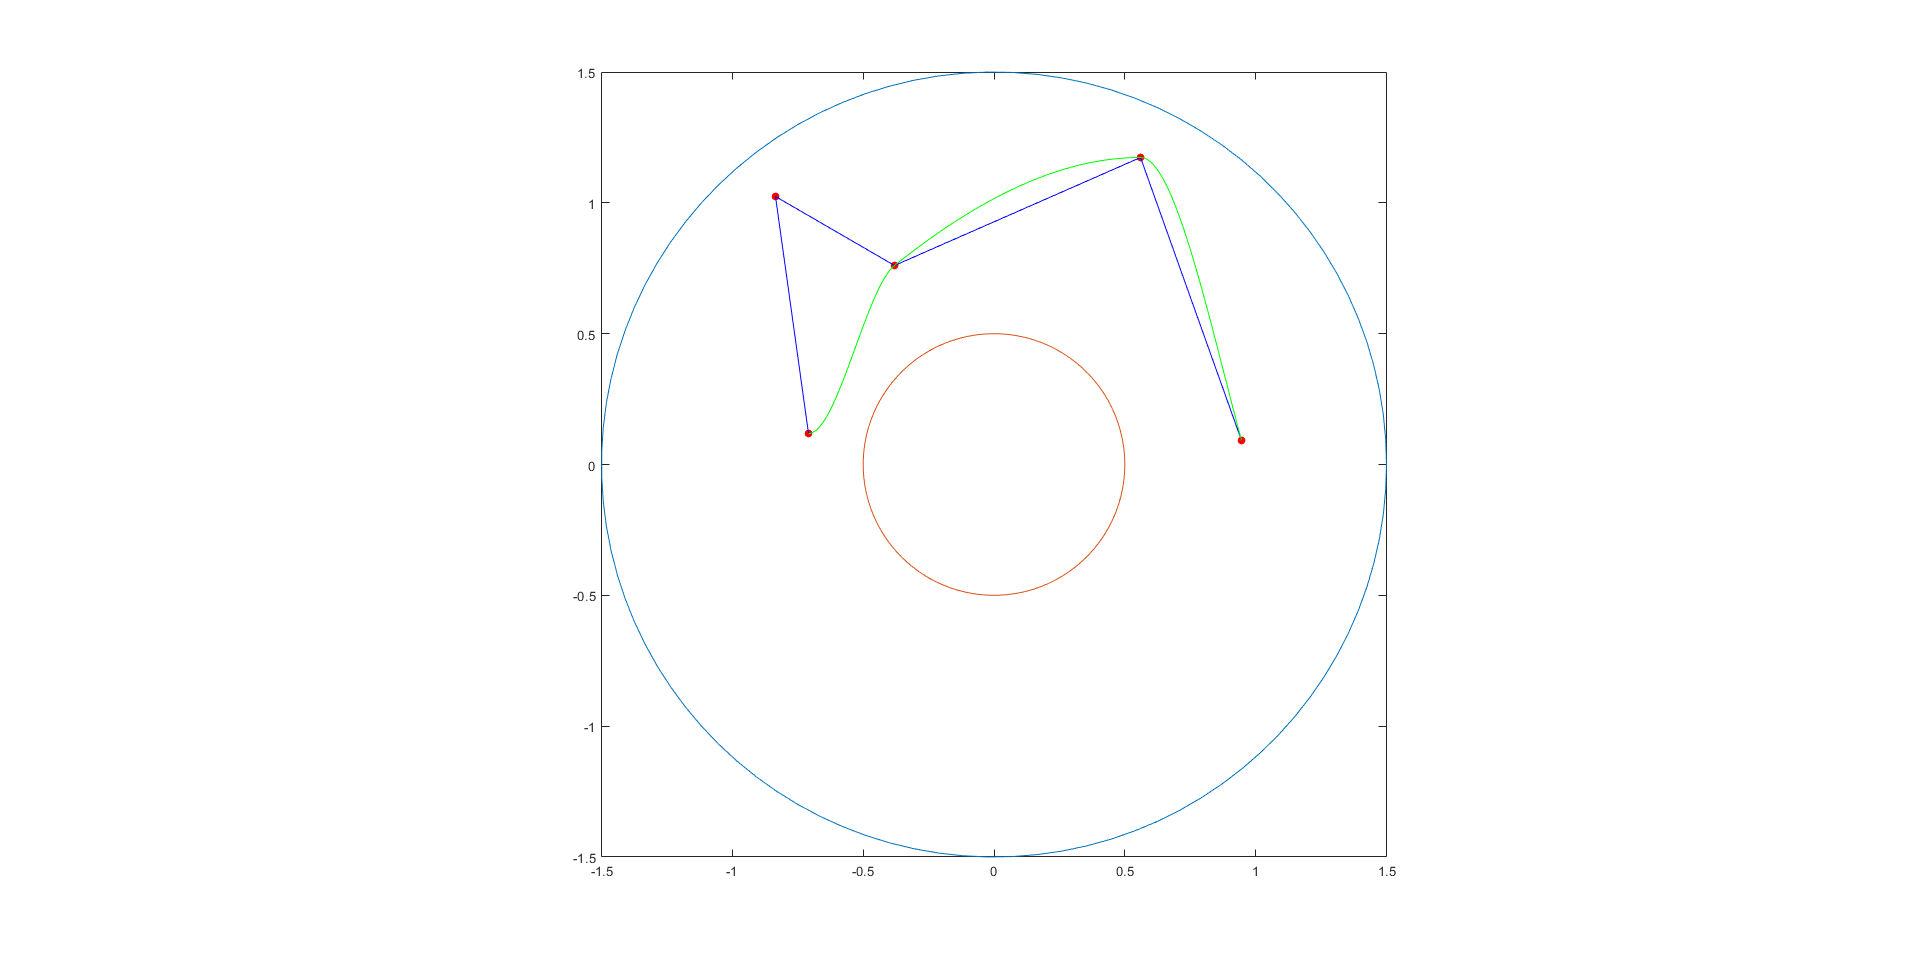


%Plotting the Interpolation Curve
x3 = linspace(x(1),x(end),1000);

if clicks >= 4
    pp = interp1(x,y,x3,'pchip');
    plot(x3,pp,'-g')
    hold off
else
    pp = interp1(x,y,x3,'makima');
    plot(x3,pp,'-g')
    hold off
end

A for loop was used to loop through the the various points on the interpolation curve. Theta1 and theta0 were calculated and then those values gave the coordiantes for the links [1]. Also, getframe allowed for an mp4 to be created.

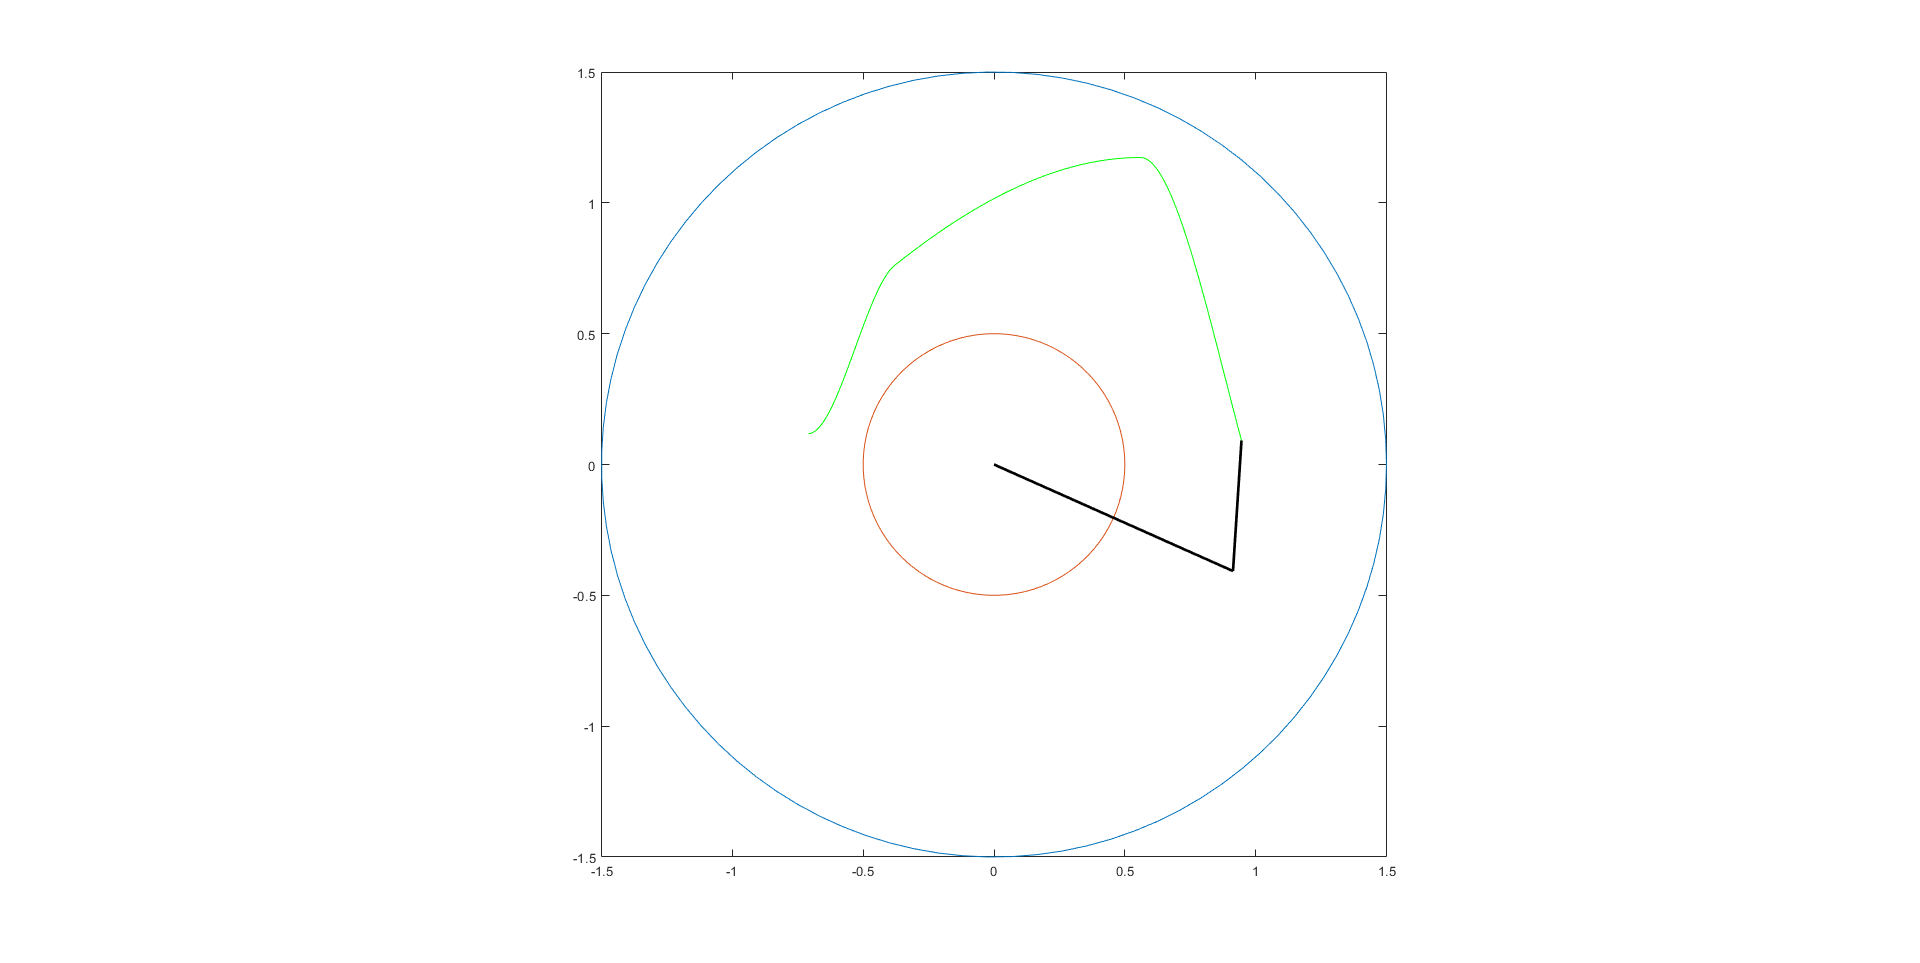

for i = 1:length(pp)
    
    theta1 = acos((x3(i)^2+pp(i)^2-(1)^2-(0.5)^2)/(2*1*0.5));
    theta0 = atan2(pp(i),x3(i)) - atan2(0.5*sin(theta1),1+0.5*cos(theta1));

    xlink1 = 1*cos(theta0);
    ylink1 = 1*sin(theta0);

    xlink2 = x3(i);
    ylink2 = pp(i);
    
    theta = linspace(0,2*pi);

    %Outer Circle
    radius = 1.5;
    x1 = radius*cos(theta);
    y1 = radius*sin(theta);
    plot(x1,y1)
    axis square
    hold on

    %Inner Circle
    radius2 = 0.5;
    x2 = radius2*cos(theta);
    y2 = radius2*sin(theta);
    plot(x2,y2)

    plot(x3,pp,'-g')
     
    plot([0 xlink1],[0 ylink1],'-k',[xlink1 xlink2],[ylink1 ylink2],'-k','LineWidth',2)
    hold off
    
    F(i) = getframe(gcf); %records video

    %pause(0.0005) %pauses loop
end

% *Records Video and saves it to a file.*
newVid = VideoWriter('Programming 4 Movie.mp4', 'MPEG-4'); 
open(newVid);
writeVideo(newVid,F);

close(newVid);

    I had a few challenges associated with this project. One of the big issues I was having was with the spline interpolation. If I didn't choose nice points then the curve would be haywire and exit the bounds of the graph. To combat this, I used a different form of interpolation called pchip. Another issue I had was with points that weren't in an ascending or descending order on the x axis. If the user clicked all over the place then the curve would behave strangely. I was not able to apply a good solution to this. My guess would be to order the points from left most to right most then find the interpolation. Although, it would not follow the users wanted path. I also could not find a good method for not allowing the curve to go within the inner-most circle. Some good potential practices would be to create phantom points along the edge, or even if the curve goes inside the curve only allow the arm to reach to its limit.

Sources:

[1] https://robotacademy.net.au/lesson/inverse-kinematics-for-a-2-joint-robot-arm-using-geometry/